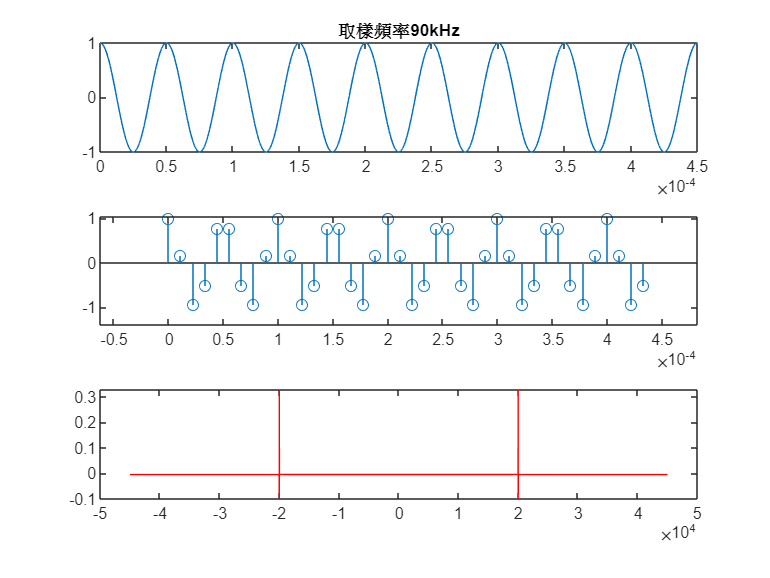

%取樣頻率90 kHz
clear all;close all
fs=90*1000; %設定取樣頻率90 kHz
ts=1/fs;
ts1=(1/10)^8;
t1=0:ts1:0.0005;
t=0:ts:1;
f=20*1000; %原始訊號頻率20 kHz
x=cos(2*pi*f*t); %取樣後的訊號
x1=cos(2*pi*f*t1); %極高取樣近似的連續波
f1=[0:(length(x)-1)]/length(x)-0.5;
X=fft(x)/length(x); %Matlab 內建的傅立葉轉換
subplot(311)
plot(t1,x1);
title('取樣頻率90kHz')
axis([0 4.5*(10)^-4 -1 1]) %限制畫圖的範圍
subplot(312)
stem(t(1:40),x(1:40));
axis([0 4.5*(10)^-4 -1 1])
subplot(313)
plot(fs*f1,fftshift(X),'r')

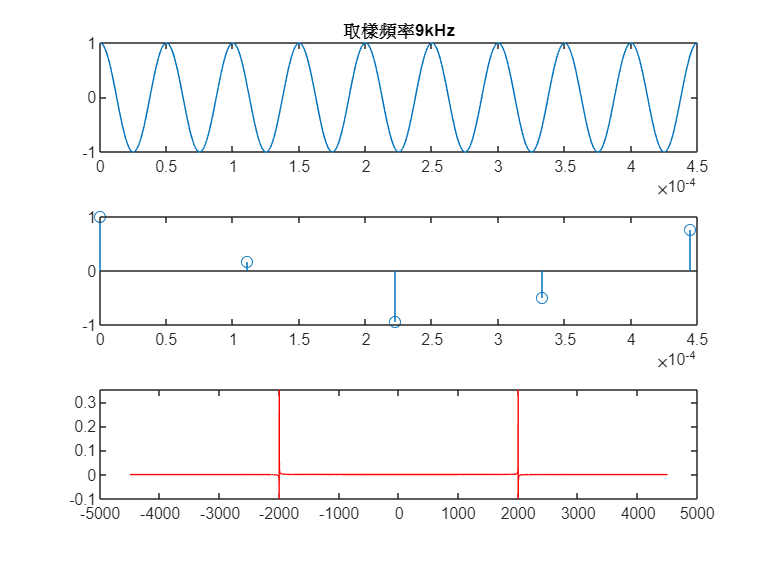

%取樣頻率9 kHz
clear all;close all
fs=9*1000; %設定取樣頻率9 kHz
ts=1/fs;
ts1=(1/10)^8;
t1=0:ts1:0.0005;
t=0:ts:1;
f=20*1000; %原始訊號頻率20 kHz
x=cos(2*pi*f*t); %取樣後的訊號
x1=cos(2*pi*f*t1); %極高取樣近似的連續波
f1=[0:(length(x)-1)]/length(x)-0.5;
X=fft(x)/length(x); %Matlab 內建的傅立葉轉換
subplot(311)
plot(t1,x1);
title('取樣頻率9kHz')
axis([0 4.5*(10)^-4 -1 1]) %限制畫圖的範圍
subplot(312)
stem(t(1:40),x(1:40));
axis([0 4.5*(10)^-4 -1 1])
subplot(313)
plot(fs*f1,fftshift(X),'r')